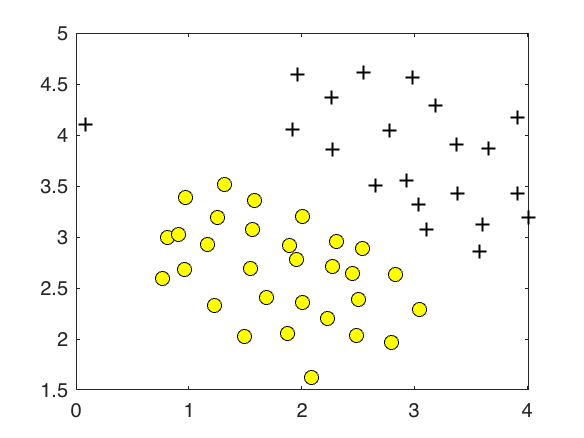

data1= load("data1(1).mat");
figure;
plotData(data1.X, data1.y)


model=svmTrain(data1.X, data1.y, 150, @linearKernel);


Training ......................................................................
...............................................................................
...............................................................................
.......... Done! 



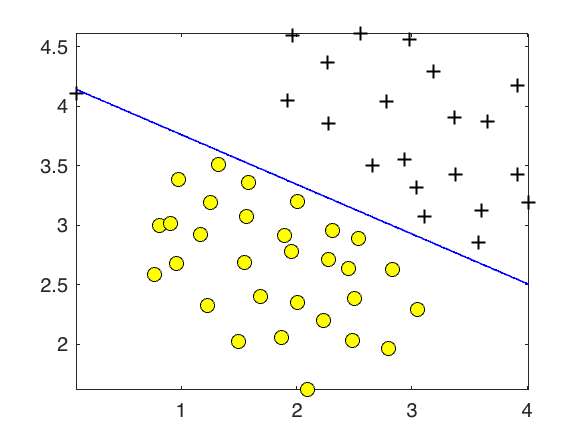

figure;
visualizeBoundary(data1.X, data1.y, model);

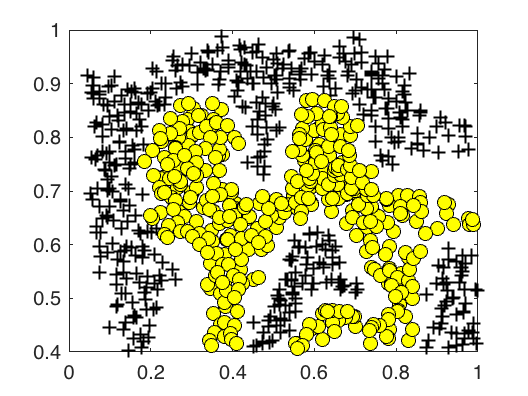

data2= load("data2(1).mat");
figure;
plotData(data2.X, data2.y);


model= svmTrain(data2.X, data2.y, 200, @(x1,x2) gaussianKernel(x1, x2, 0.09));

Error using warmup
Too many input arguments.

Error in svmTrain (line 62)
    kF=kernelFunction(1, 0, 1)

visualizeBoundary(data2.X, data2.y, model);


data3= load("data3(1).mat");
figure;
plotData(data3.X, data3.y);


linear_model= svmTrain(data3.X, data3.y, 150, @linearKernel);


Training ......................................................................
...............................................................................
...............................................................................
...............................................................................
.................................................... Done! 



gaussian_model= svmTrain(data3.X, data3.y, 150, @(x1, x2) gaussianKernel(x1,x2, 0.1));


Training ......................................................................
...............................................................................
...............................................................................
...............................................................................
...............................................................................
...............................................................................
...............................................................................
...............................................................................
...............................................................................
...............................................................................
...............................................................................
...............................................................................
.......................................

figure;
visualizeBoundary(data3.X, data3.y, linear_model);
hold on;
visualizeBoundary(data3.X, data3.y, gaussian_model);

% z=gaussianKernel(data3.X, data3.y, 0.1);
gaussianKernel(1,0)

Not enough input arguments.

Error in gaussianKernel (line 9)
sim = exp(-(norm(x1 - x2) ^ 2) / (2 * (sigma ^ 2)));